# Topic 2: Binary Data and Spread Spectrum

# Communications

## Introduction

% Parameters to tweak
signal_length = 10;
M  =10;
Pn = 5;

function binary_signal = binary_data_gen(signal_length)
    binary_signal = randi([0, 1],1, signal_length);
end

function mod_signal = modulator(M, binary_signal)
    y_bin = (2 * binary_signal - 1);
    mod_signal = repelem(y_bin, M);
end

function noisy_mod_signal = noise_generator(noise_power,mod_signal)
    a = sqrt(noise_power*3);
    noisy_mod_signal = mod_signal;
    for i=1:length(mod_signal)
        noisy_mod_signal(i) = mod_signal(i) + (rand * 2   - 1)*a;
    end
end

function demod_signal = demodulator(M,noisy_mod_signal)

    num_parts = ceil(length(noisy_mod_signal) / M); % how many sections of M are there - rounded up
    demod_signal = zeros(1,num_parts); % prep output vector
    
    for i = 1:num_parts
        start_idx = (i - 1) * M + 1;
        end_idx = min(i * M, length(noisy_mod_signal)); % Handle the last part if not a full M
        demod_signal(i) = sum(noisy_mod_signal(start_idx:end_idx));
    end
end

function [detected_bin, err] = detector(binary_signal,demod_signal) 
    detected_bin = (demod_signal >= 0);
    err = sum(abs(binary_signal - detected_bin));
end

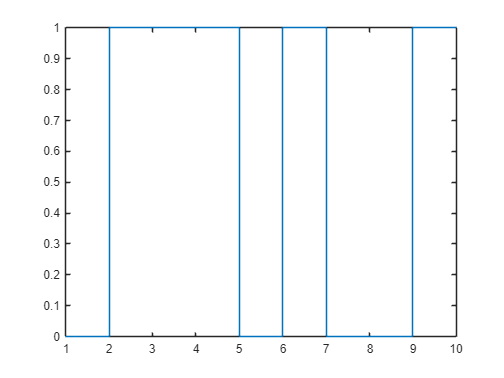

binary_signal = binary_data_gen(signal_length);
stairs(binary_signal)

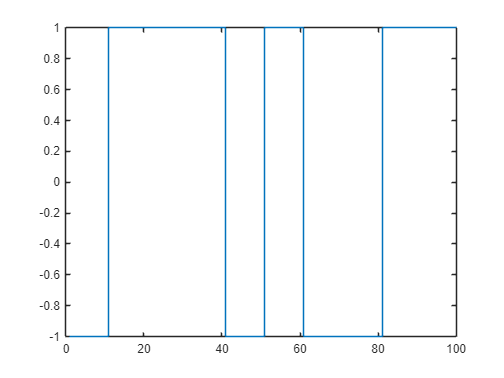

mod_signal = modulator(M,binary_signal);
stairs(mod_signal)

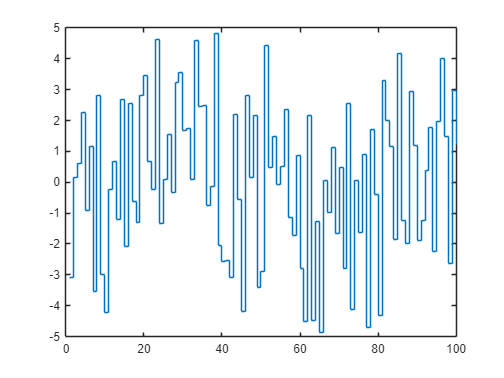

noisy_mod_signal = noise_generator(Pn,mod_signal);
stairs(noisy_mod_signal)

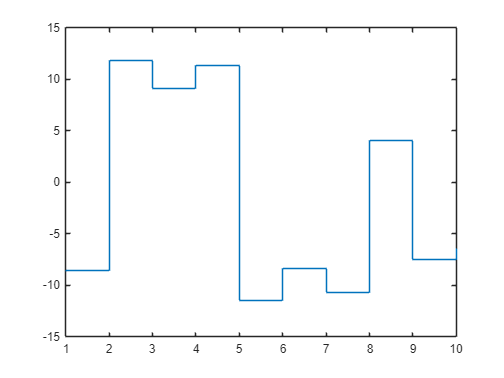



demod_signal = demodulator(M,noisy_mod_signal);
stairs(demod)

[detected_bin, err] = detector(binary_signal, demod_signal);
err

err = 0

stairs(detected_bin)